CREDITS

Made by Rahul S. Yerrabelli under Nai-Kong Cheung, MD, PhD at Memorial Sloan Kettering Cancer Center. This is part of the code accompanying the publication of "**Intra-Ommaya Compartmental Radioimmunotherapy using 131I-Omburtamab— Pharmacokinetic Modeling to Optimize Therapeutic Index**" (doi:10.1007/s00259-020-05050-z). See that paper and its supplement file for a greater description of the model and results.

FILE INFO

This file runs the model with different immunoreactivity and activity values. It is presented as Figure 3

Simulations.DefaultValues;

normIR = immunoreactivity; % save default immunoreactivity so you can calculate % change in outcomes from standard IR
activityAdmin=50; %mCi;

% Use this to check how the numbers change if R0 changes
%tumorload = tumorload*10; %tumorload is R0 in mol/L


immunoreactivities = 0:.01:1; % range of immunoreactivities being tested

Load simulation data if it was already done before. Otherwise skip this block.

load(['+Simulations/IR/BetterLabels/ys_for' num2str(activityAdmin) 'mCi, R0=' num2str(tumorload*6.022e23/1000,'%0.1e') ', S=' num2str(S) '.mat'])

Use this to calculate IR if it is not already saved. Otherwise skip this block.

tic
ys = zeros(3,length(immunoreactivities));
for i = 1:length(immunoreactivities)
    immunoreactivity = immunoreactivities(i);
    defined_params = [immunoreactivity, tumorload, perTV, perNB, ...
        kAR, k_AR, V, n, MM, cI0, t_half, S];
    [t, cIobs, AUC_cIAR, AUC_cIA] = solveModel(activityAdmin,...
        Vv, CL, time_values_needed,defined_params);
    therap_ratio = [AUC_cIAR AUC_cIA AUC_cIAR/AUC_cIA];
    
    ys(:,i) = therap_ratio;
    toc
end

Elapsed time is 1.377695 seconds.


Elapsed time is 2.740027 seconds.


Elapsed time is 4.085201 seconds.


Elapsed time is 5.383081 seconds.


Elapsed time is 6.630856 seconds.


Elapsed time is 7.867767 seconds.


Elapsed time is 9.111392 seconds.


Elapsed time is 10.342428 seconds.


Elapsed time is 11.537134 seconds.


Elapsed time is 12.929713 seconds.


Elapsed time is 14.262794 seconds.


Elapsed time is 15.514228 seconds.


Elapsed time is 16.812687 seconds.


Elapsed time is 18.052704 seconds.


Elapsed time is 19.263244 seconds.


Elapsed time is 20.452698 seconds.


Elapsed time is 21.662144 seconds.


Elapsed time is 22.859625 seconds.


Elapsed time is 24.068352 seconds.


Elapsed time is 25.268759 seconds.


Elapsed time is 26.489913 seconds.


Elapsed time is 27.691913 seconds.


Elapsed time is 28.899077 seconds.


Elapsed time is 30.108722 seconds.


Elapsed time is 31.307150 seconds.


Elapsed time is 32.512018 seconds.


Elapsed time is 33.715017 seconds.


Elapsed time is 34.906463 seconds.


Elapsed time is 36.120298 seconds.


Elapsed time is 37.304227 seconds.


Elapsed time is 38.486109 seconds.


Elapsed time is 39.669073 seconds.


Elapsed time is 40.859022 seconds.


Elapsed time is 42.057717 seconds.


Elapsed time is 43.250479 seconds.


Elapsed time is 44.442433 seconds.


Elapsed time is 45.624032 seconds.


Elapsed time is 46.816334 seconds.


Elapsed time is 47.989309 seconds.


Elapsed time is 49.169459 seconds.


Elapsed time is 50.345308 seconds.


Elapsed time is 51.533267 seconds.


Elapsed time is 52.713415 seconds.


Elapsed time is 53.896112 seconds.


Elapsed time is 55.106966 seconds.


Elapsed time is 56.302874 seconds.


Elapsed time is 57.500356 seconds.


Elapsed time is 58.710127 seconds.


Elapsed time is 59.909655 seconds.


Elapsed time is 61.120160 seconds.


Elapsed time is 62.331067 seconds.


Elapsed time is 63.519383 seconds.


Elapsed time is 64.700681 seconds.


Elapsed time is 65.918996 seconds.


Elapsed time is 67.133412 seconds.


Elapsed time is 68.332073 seconds.


Elapsed time is 69.530157 seconds.


Elapsed time is 70.719834 seconds.


Elapsed time is 71.918039 seconds.


Elapsed time is 73.130896 seconds.


Elapsed time is 74.320467 seconds.


Elapsed time is 75.479302 seconds.


Elapsed time is 76.633963 seconds.


Elapsed time is 77.804023 seconds.


Elapsed time is 79.003362 seconds.


Elapsed time is 80.175161 seconds.


Elapsed time is 81.353164 seconds.


Elapsed time is 82.524528 seconds.


Elapsed time is 83.701256 seconds.


Elapsed time is 84.878553 seconds.


Elapsed time is 86.071401 seconds.


Elapsed time is 87.266188 seconds.


Elapsed time is 88.428053 seconds.


Elapsed time is 89.617799 seconds.


Elapsed time is 90.780860 seconds.


Elapsed time is 91.970687 seconds.


Elapsed time is 93.147509 seconds.


Elapsed time is 94.317301 seconds.


Elapsed time is 95.488121 seconds.


Elapsed time is 96.675082 seconds.


Elapsed time is 97.859369 seconds.


Elapsed time is 99.165498 seconds.


Elapsed time is 100.351993 seconds.


Elapsed time is 101.736706 seconds.


Elapsed time is 103.097646 seconds.


Elapsed time is 104.479962 seconds.


Elapsed time is 105.906988 seconds.


Elapsed time is 107.282221 seconds.


Elapsed time is 108.712478 seconds.


Elapsed time is 110.180132 seconds.


Elapsed time is 111.665249 seconds.


Elapsed time is 113.146057 seconds.


Elapsed time is 114.628260 seconds.


Elapsed time is 116.045726 seconds.


Elapsed time is 117.541287 seconds.


Elapsed time is 118.835388 seconds.


Elapsed time is 120.083679 seconds.


Elapsed time is 121.377430 seconds.


Elapsed time is 122.670096 seconds.


Elapsed time is 123.929987 seconds.


Elapsed time is 125.201768 seconds.


Save to file for future use

save(['+Simulations/IR/BetterLabels/ys_for' num2str(activityAdmin) 'mCi, R0=' num2str(tumorload*6.022e23/1000,'%0.1e') ', S=' num2str(S) '.mat'],'ys');

size(ys(3, abs(immunoreactivities-immunoreactivity)<1e-4))

ans =      1     1


Make plots. These correspond to Figure 3 in the paper.

fontsize = 12; %48;
axislinewidth = 1.5; %6;
plotlinew = 4; %16;
showtitles = false;


figure;
hold on; grid minor; %Don't do box on because it would override the outline of the TR increase

% Plot the simulated data 
plot(immunoreactivities*100, ys(3,:),'LineWidth',plotlinew);

% Plot a linear regression with fixed y intercept
m=immunoreactivities'\(ys(3,:)-ys(3,1))';
regress = m*immunoreactivities+ys(3,1);
plot(immunoreactivities*100, regress,'--','LineWidth',plotlinew/3);

immunoreactivity = normIR;
[~,I] = min(abs(immunoreactivities-immunoreactivity));%<1e-4
currTI = ys(3,I);
maxTI = max(ys(3,end));
plot(immunoreactivity*100, currTI,'bo','MarkerSize',10,'LineWidth',plotlinew);


yl = get(gca,'Ylim'); xl = get(gca,'Xlim'); 
plot([xl(1) xl(2) xl(2)-eps],...
    [currTI currTI, maxTI],'b:','LineWidth',plotlinew/3);
potentIncrease = (maxTI-currTI)/currTI*100
text(xl(2),mean([currTI,maxTI]), ...
    {[' ' num2str(potentIncrease,3) '%'];' ↑TR'},'FontSize',fontsize*4/6,'FontName','Arial')

ylim([0 1.5*currTI]);
yticks([0:.25:1.5]*currTI);
set(gca,'yticklabel',num2str(get(gca,'ytick')'/currTI*100-100,'%.0f%%'));

potentIncrease = 17.4500

xticks([0:20:100]);
set(gca,'xticklabel',num2str(get(gca,'xtick')','%.0f%%'));
xlabel('Immunoreactivity (IR) %','FontWeight','bold');
ylabel('% Change in TI','FontWeight','bold');
if showtitles
    title({['Effect of IR on Therapeutic'],['Index (TI) for a '...
        num2str(activityAdmin) 'mCi Dose']});
end

legend({'Model Prediction','Linear Regression','Current Value'},'Position',[0.67 0.28 0 0]);
[maxdiff, I] =max(-ys(3,:)+regress); 
% max overshoot happens at 0.371     0.071519
% max undershooting happens at 1, err 0.12441
[immunoreactivities(I) maxdiff]

ans =     1.0000    0.0078


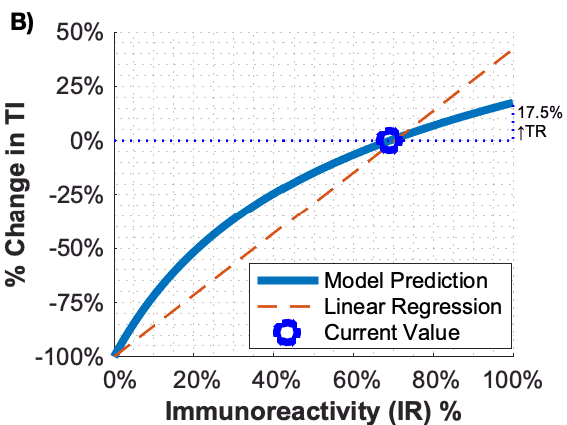



% Add A), B), C) etc text here
if activityAdmin == 2
    letter='A';
elseif activityAdmin == 35
    letter='B';
elseif activityAdmin == 50
    letter='B'; % Had this code when I was going to include 35mCi in figure.
else
    letter='D';
end
xloc=0; yloc = 1;
if (yloc >= 0) && (yloc <= 1) && (xloc >= 0) && (xloc <= 1) %otherwise will throw error
    %Letter should be in 12pt helvetica font, regardless of the font of the rest of the figures, per JNM
    annotation('textbox', [xloc, yloc, 0, 0], 'string', strcat(letter,')'),'FontSize',12,'fontname','helvetica', 'FontWeight', 'bold','tag','FigurePartLetter');
end


set(gca,'FontSize',fontsize, 'FontName','Arial'); %Arial for figure text, Helvetica for labels
set(gcf,'PaperPositionMode','Manual');
set(gcf,'PaperUnits','centimeters','PaperPosition', [0 0 10 7.5]); %for saving the file
set(gcf,'Units','centimeters','Position', [0 0 10 7.5]); %for showing up in the mlx file
print(['Figures/Immunoreactivity/IRfor' num2str(activityAdmin) 'mCi, S=' num2str(S)], '-dpng', '-r600'); %<-Save as PNG with certain DPI
print(['Figures/Immunoreactivity/IRfor' num2str(activityAdmin) 'mCi, S=' num2str(S)], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI
print(['Figures/Immunoreactivity/IRfor' num2str(activityAdmin) 'mCi, S=' num2str(S) ' 300p'], '-dtiff', '-r300'); %<-Save as TIFF with certain DPI

Find equivalent of Km for the hyperbolic, as well as the 10% to 90% increase amount.

% For Therapeutic Index Curve
Km=(sum(ys(3,:) <= 1/2*ys(3,end))-1)/length(ys(3,:))

Km = 0.2574

lgincrease = (ys(:,90+1)-ys(:,10+1))./ys(:,10+1);
smincrease = (ys(:,100+1)-ys(:,69+1))./ys(:,69+1);

corrcoef(ys(3,:), ys(1,:))

ans =     1.0000    1.0000
    1.0000    1.0000
